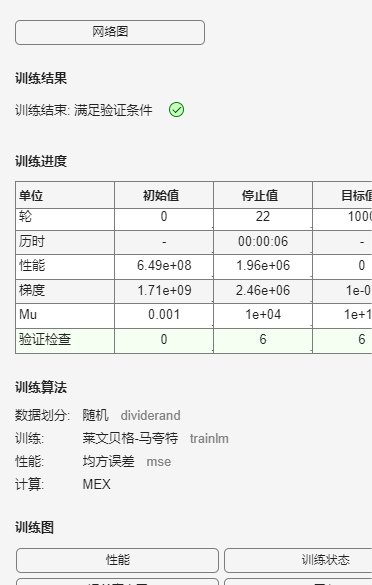

% 精简GDP预测模型实例和应用：
% 修改代码时注意变量名末尾是否有上标hat(')，有的话修改时注意在对应位置保留
% 涉及到矩阵维度匹配的问题请一定注意

% 一、加载数据：
data = readtable('dataset.csv');  % 可自定义地址
inputs = data{:, 1:7};            % 前n列是输入特征
targets = data{:, 8};             % 最后一列是GDP值

% 二、划分数据集：
cv = cvpartition(size(data, 1), 'HoldOut', 0.1);
idxTrain = training(cv);  % 90%的数据为训练集
idxTest = test(cv);       % 10%的数据为测试集

inputsTrain = inputs(idxTrain, :);    % 训练输入
targetsTrain = targets(idxTrain, :);  % 训练对比
inputsTest = inputs(idxTest, :);      % 测试输入
targetsTest = targets(idxTest, :);    % 测试对比

% 三、创建神经网络模型：输入层（7）->隐藏层（5）->输出层（1）
hiddenLayerSize = 5;            % 设置一个含10个神经元的隐藏层
net = fitnet(hiddenLayerSize);  % 定义一个适用于回归任务的简单的fitnet网络

% 四、训练神经网络：
net = train(net, inputsTrain', targetsTrain');

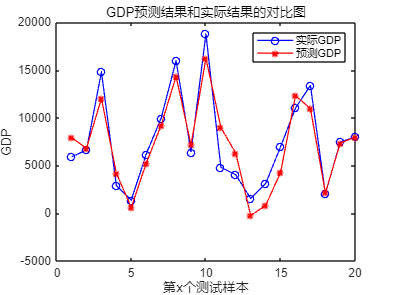


% 五、测试神经网络：
predictions = net(inputsTest');                        % 得到具体的预测值
performance = perform(net, targetsTest', predictions); % 模型评价

% 六、计算每个测试样本的百分比偏差：
percentageError = abs((predictions - targetsTest') ./ targetsTest') * 100;

% 七、计算平均百分比偏差：
meanPercentageError = mean(percentageError);

% 八、观察一些可视化结果：
figure;
plot(targetsTest', 'bo-', 'LineWidth', 1);
hold on;
plot(predictions, 'r*-', 'LineWidth', 1);
legend('实际GDP', '预测GDP');
title('GDP预测结果和实际结果的对比图');
xlabel('第x个测试样本');
ylabel('GDP');

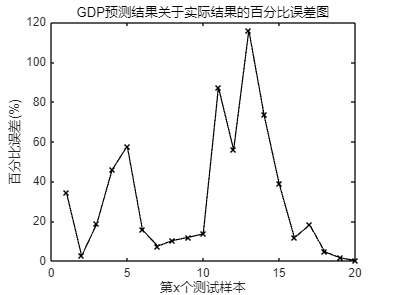


figure;
plot(percentageError, 'kx-', 'LineWidth', 1);
title('GDP预测结果关于实际结果的百分比误差图');
xlabel('第x个测试样本');
ylabel('百分比误差(%)');


% 九、显示测试后的平均百分比误差结果
disp(['测试集平均百分比误差: ', num2str(meanPercentageError), '%']);

测试集平均百分比误差: 31.2597%



% 推荐尝试修改的变量：

% (1)inputs中选取的列："1,7"两个数字可以根据希望给到模型的输入来修改

% (2)cv定义时最后的"0.1"这个数值：0-1范围内取值，决定训练集和测试集大小

% (3)hiddenLayerSize：隐藏层的设置，采取[a_1,a_2, ..., a_n]的定义方式
%%也可以直接用一个常数，应注意控制每一层隐藏层神经元数目和隐藏层总数
%%都不建议取超过100的值以保障模型的稳定和适用性（a_n的具体值和n都不建议太大）

% Ps：作为一个入门了解的小实验，只建议修改测试上述参数，如果想深入了解神经
%%网络和深度学习，可以试着深入学习修改上述模型，采取包括但不限于进行数据归一化，
%%了解matlab配备的针对不同问题的解决模型，学习怎样合理设置模型网络参数之类的方式。